# Run Your Function

Calling with output

This works correctly.

M = multtable(6, 4)

M =      1     2     3     4
     2     4     6     8
     3     6     9    12
     4     8    12    16
     5    10    15    20
     6    12    18    24


**Calling with no output**

This currently returns a matrix multiplication table as output, but you will fix it so it does not.

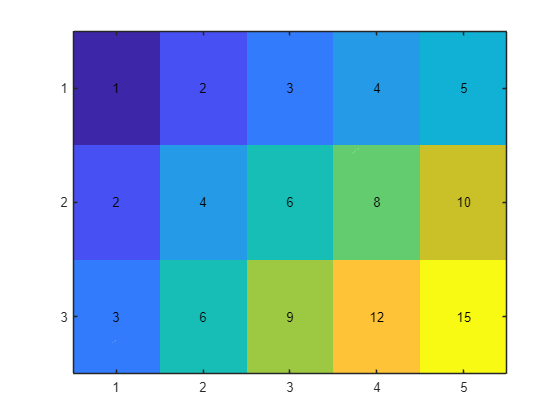

multtable(3, 5)

# Create a multiplication table

`n` is a numeric vector

`M` is a matrix of the integers 1 through `n(1)` multiplied by the integers 1 through `n(2)`.  If `n` is a scalar, `M` is a square matrix of the integers 1 through `n` multiplied by the integers 1 through `n`.

## Examples

`M = multtable(6,4)`

`M = multtable(4)`

`multtable(3,5)`

The function `multtable` creates a table of the integers 1 through `m` multiplied by the integers 1 through `n`. It also creates a visualization of the result.

function Mout = multtable(m,n)
    % Deal with missing inputs
    if nargin < 2
        n = m;
    end
    
    % Calculate table
    M = (1:m)' .* (1:n);
    
    % TASK 1:
    % ENTER TASK 1 CODE HERE:
    if nargout
        Mout = M;
    else
        % Make plot
        imagesc(sqrt(M))
        yticks(1:m)
        xticks(1:n)
        [r,c] = ind2sub([m,n],(1:numel(M))');
        text(c,r,string(M(:)),"HorizontalAlignment","center")
    end
end